clear
close
clc
load(['Result_comp.mat'])

value_start = 1;
value_end = 100;
ligth_start_coordX = 0:0.1:10;
Int_result = zeros(size(result,1),value_end-value_start+1,value_end-value_start+1);
for i = 1:size(result,1)
    Int_result(i,:,:) = 2*pi*0.1*ligth_start_coordX(i)*result(i,value_start:value_end,value_start:value_end);
end
Int_result_sum = sum(Int_result,1);
Int_sum(:,:) = Int_result_sum(1,:,:);
Int_sum1 = Int_sum(:,:);
det(Int_sum1)

ans = 3.7155e+294

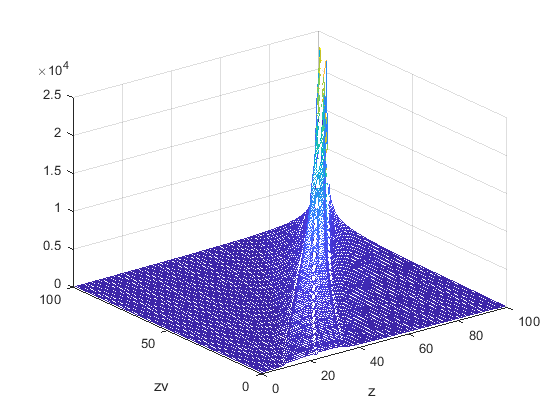

eig_abs = abs(eig(Int_sum1));
IInv = inv(Int_sum1);

pr = Int_sum1/IInv;
figure
mesh(Int_sum1)
xlabel('z')
ylabel('zv')

eig_values = eig(Int_sum1);
moduleeig = abs(eig_values);

close
resultsum = sum(result,1);
resultsum_1(value_start:value_end,value_start:value_end) = resultsum(1,value_start:value_end,value_start:value_end);
resultsum_11 = sum(resultsum_1(:,value_start:value_end),1);
b = resultsum_11/Int_sum1;
a = resultsum_11/Int_sum1;
figure
plot(a, 'LineWidth',0.1)
hold on 
plot(smooth(b,15), 'LineWidth',3)
grid on
fprintf('SKO = %d;\n', sum(smooth(b,15) - sum(smooth(b,15))/length(b))/length(b))

SKO = -4.357625e-17;


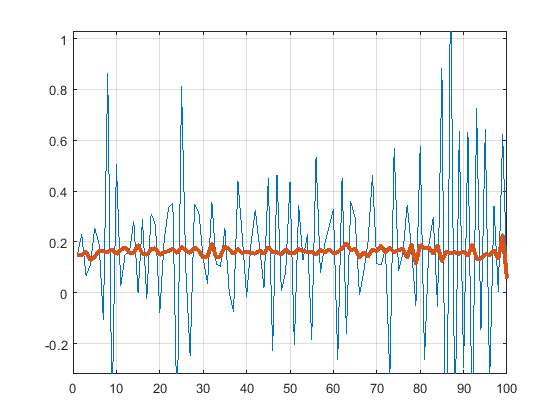

xlim([value_start value_end])
ylim([0 0.4])

% -4.3326e-17
% 5.6843e-16
xlim([0.0 100.0])
ylim([-0.32 1.03])

% sum(a)
sum(b)

ans = 16.4181

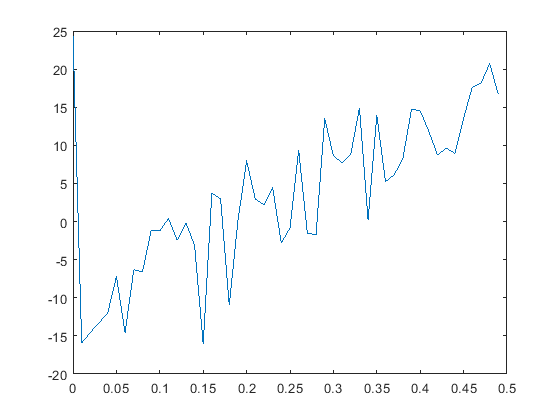

specplot(b, 1)

Z = diag(resultsum_11)